s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



% Generate open loop transfer function for the aircraft
P_pitch = tf([1.151, 0.1774], [1,0.739, 0.921,0])

P_pitch =
 
      1.151 s + 0.1774
  -------------------------
  s^3 + 0.739 s^2 + 0.921 s
 
Continuous-time transfer function.



% Analyze open loop response with 0.2 radian input
t = [0:0.1:10]

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


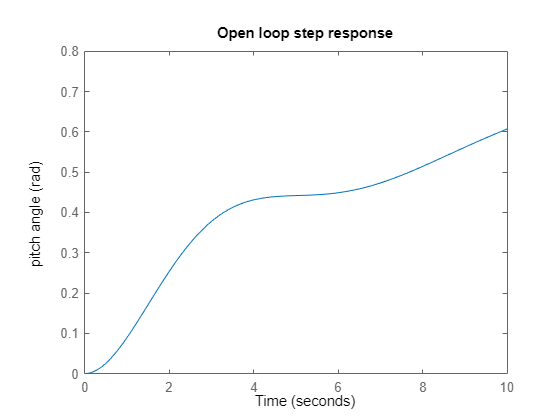

step(0.2*P_pitch,t)
axis([0 10 0 0.8]);
ylabel('pitch angle (rad)')
title('Open loop step response')

pole(P_pitch)

ans =    0.0000 + 0.0000i
  -0.3695 + 0.8857i
  -0.3695 - 0.8857i


% Closed loop feedback response analysis
sys_cl = feedback(P_pitch,1)

sys_cl =
 
           1.151 s + 0.1774
  ----------------------------------
  s^3 + 0.739 s^2 + 2.072 s + 0.1774
 
Continuous-time transfer function.



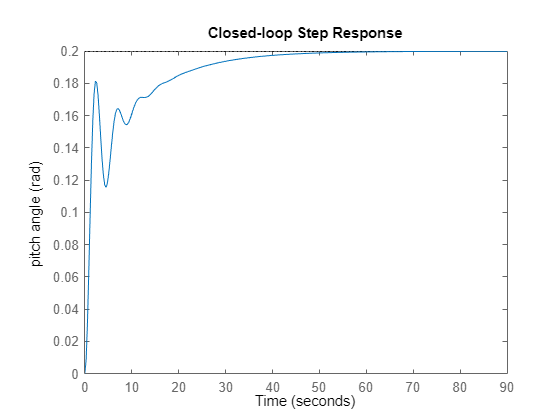

step(0.2*sys_cl)
ylabel('pitch angle (rad)')
title('Closed-loop Step Response')

poles = pole(sys_cl)

poles =   -0.3255 + 1.3816i
  -0.3255 - 1.3816i
  -0.0881 + 0.0000i


% Sımplify output function which is 4th order (assuming step input)
% ZPK factors out numerator and denominator to simpler terms so we can see
% zeros and poles
R = 0.2/s 

R =
 
  0.2
  ---
   s
 
Continuous-time transfer function.



Y = zpk(sys_cl * R)

Y =
 
            0.2302 (s+0.1541)
  -------------------------------------
  s (s+0.08805) (s^2 + 0.6509s + 2.015)
 
Continuous-time zero/pole/gain model.



% Split output Y expression into partial fractions 
[r,p,k] = residue(0.2*[1.151 0.1774],[1 0.739 2.072 0.1774 0])

r =   -0.0560 + 0.0160i
  -0.0560 - 0.0160i
  -0.0879 + 0.0000i
   0.2000 + 0.0000i


p =   -0.3255 + 1.3816i
  -0.3255 - 1.3816i
  -0.0881 + 0.0000i
   0.0000 + 0.0000i



k =

     []



% R contains numerator coefficients. P contains poles of the system in
% order.
% Now combine the first two complex conjugate coefficients to one
[num,den] = residue(r(1:2),p(1:2),k)

num =    -0.1121   -0.0807


den =     1.0000    0.6509    2.0147


tf(num,den)

ans =
 
   -0.1121 s - 0.08071
  ----------------------
  s^2 + 0.6509 s + 2.015
 
Continuous-time transfer function.




% Perform inverse laplace on final expression 
[num1,den1] = residue(r(3),p(3),k)

num1 = -0.0879

den1 =     1.0000    0.0881


[num2,den2] = residue(r(4),p(4),k)

num2 = 0.2000

den2 =      1     0


[num3,den3] = residue(r(1:2),p(1:2),k)

num3 =    -0.1121   -0.0807


den3 =     1.0000    0.6509    2.0147



y1 = tf(num1,den1)

y1 =
 
    -0.0879
  -----------
  s + 0.08805
 
Continuous-time transfer function.



y2 = tf(num2,den2)

y2 =
 
  0.2
  ---
   s
 
Continuous-time transfer function.



y3 = tf(num3,den3)

y3 =
 
   -0.1121 s - 0.08071
  ----------------------
  s^2 + 0.6509 s + 2.015
 
Continuous-time transfer function.



% Plot time function
t = [0:0.1:70]

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


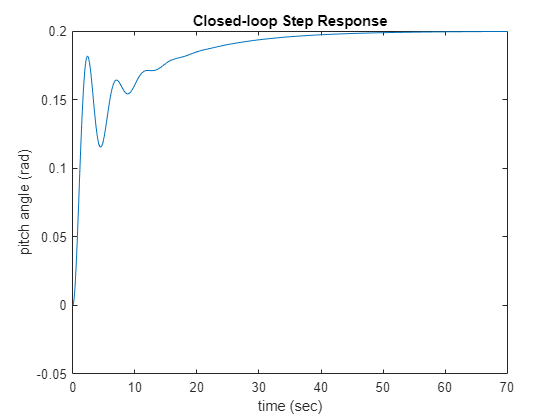

y = 0.2 - 0.0881*exp(-0.08805*t) - exp(-0.3255*t).*(0.1121*cos(1.3816*t)+0.0320*sin(1.3816*t));
plot(t,y)
xlabel('time (sec)')
ylabel('pitch angle (rad)')
title('Closed-loop Step Response')

% PID Controller Design in Time Domain

% Redefine system
s = tf('s');
P_pitch = (1.151*s+0.1774)/(s^3+0.739*s^2+0.921*s);

% Proportional Control
controlSystemDesigner(P_pitch)

% Root locus analysis
% First analyse with just a proportional controller
s = tf('s');
P_pitch = (1.151*s+0.1774)/(s^3+0.739*s^2+0.921*s);
controlSystemDesigner('rlocus', P_pitch)

Error using controlSystemDesigner (line 230)
Operands to the logical and (&&) and or (||) operators must be convertible to logical scalar values.

% Frequency Domain Methods for Controller Design
% Closed-loop response

sys_cl = feedback(P_pitch,1)
poles = pole(sys_cl)

% Geenrate bode plots with gain and phase margins
% Gain and phase amrgins indicate stability just like the negative part of
% poles indicate stabiltiy
margin(P_pitch), grid

% The belwoa pepars to give a false result
fb = bandwidth(sys_cl, -3)

% Plot step resposne to show stability
sys_cl = feedback(P_pitch,1);
step(0.2*sys_cl), grid
ylabel('pitch angle (rad)');
title('Closed-loop Step Response')

% Lead Compensation
% This will introduce a positive phase lag and increase gain at higher
% frequencies

%  First employ gain 10
K = 10;
margin(K*P_pitch), grid
figure;
sys_cl = feedback(K*P_pitch,1);
step(0.2*sys_cl), grid
title('Closed-loop Step Response with K = 10')

% Now compensator
K = 10;
alpha = 0.20;
T = 0.52;
C_lead = K*(T*s + 1) / (alpha*T*s + 1);
margin(C_lead*P_pitch), grid


sys_cl = feedback(C_lead*P_pitch,1);
step(0.2*sys_cl), grid
title('Closed-loop Step Response with K = 10, \alpha = 0.10, and T = 0.52')

% Modify parameters to reduce overshoot
K = 10;
alpha = 0.04;
T = 0.55;
C_lead = K*(T*s + 1) / (alpha*T*s + 1);
sys_cl = feedback(C_lead*P_pitch,1);
step(0.2*sys_cl), grid
title('Closed-loop Step Response with K = 10, \alpha = 0.04, and T = 0.55')

stepinfo(0.2*sys_cl)

sys_cl

sys_cl =
 
           1.151 s + 0.1774
  ----------------------------------
  s^3 + 0.739 s^2 + 2.072 s + 0.1774
 
Continuous-time transfer function.

